## Wavelets - a practical walk-though

This script shows an example wavelet analysis with 1-fold connectivity matrix, relative to sensor Oz, while calculating 

all necessary information for publication in a peer-reviewed paper. 

% first load exampe data, make sure the data are in the current directory,
% or in the path
load('bop_106.fl40h1.E1.app1.mat') % loads our example data set (129 sensors, 2551 points, 59 trials)
size(outmat)

ans =          129        2551          59


SampRate = 500; 

Experimental design and trial structure for the example data

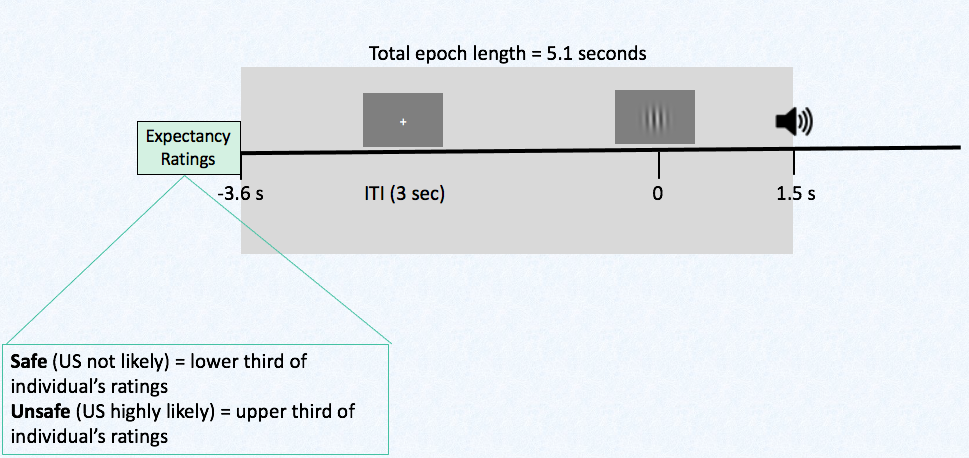

Now, calculate the frequency steps for the wavelet, the resolution/stepwidth will need to be mentioned in your manuscript

freqRes = 1000/(2551*2) % = 1000/5102 ms (2551 sample points sampled at 500 Hz)

freqRes = 0.1960

this is the possible best frequency resolution (the most steps you can have.

freqs_allpossible = 0:freqRes:SampRate./2; % 1276 possible frequencies you can look at but that is too much, and unnecessarily dense 

freqs_wanted = freqs_allpossible(20: 4: 200); % look at frequencies from 3.72 to 39 Hz 

this applies to everything that is based on a frequency transformation, not just for wavelets. You can only go worse than your native (best)

frequency resolution i.e. 1/(length in secons) Hz,  but you cannot make it better. 

f0start = 20 %This is *NOT* in Hz! this is wavelet units, see lecture slides and above

f0start = 20

f0end = 200; % stop at 
fdelta = 4; % calculate only every 4th wavelet of the ones you could do
refelec = 62; % This is Pz
outname = 'test' % this is also known as the worst filename :-) 

outname = 'test'


[WaPower, PLI, PLIdiff] = wavelet_app_mat(outmat, SampRate, f0start, f0end, fdelta, refelec, outname);

size of waveletMatrix
          46        2551

 frequency step for delta_f0 = 1 is 
    0.1960

trial index of 
    59

..........    10

..........    20

..........    30

..........    40

..........    50

.........


%phase locking, inter-site phase locking

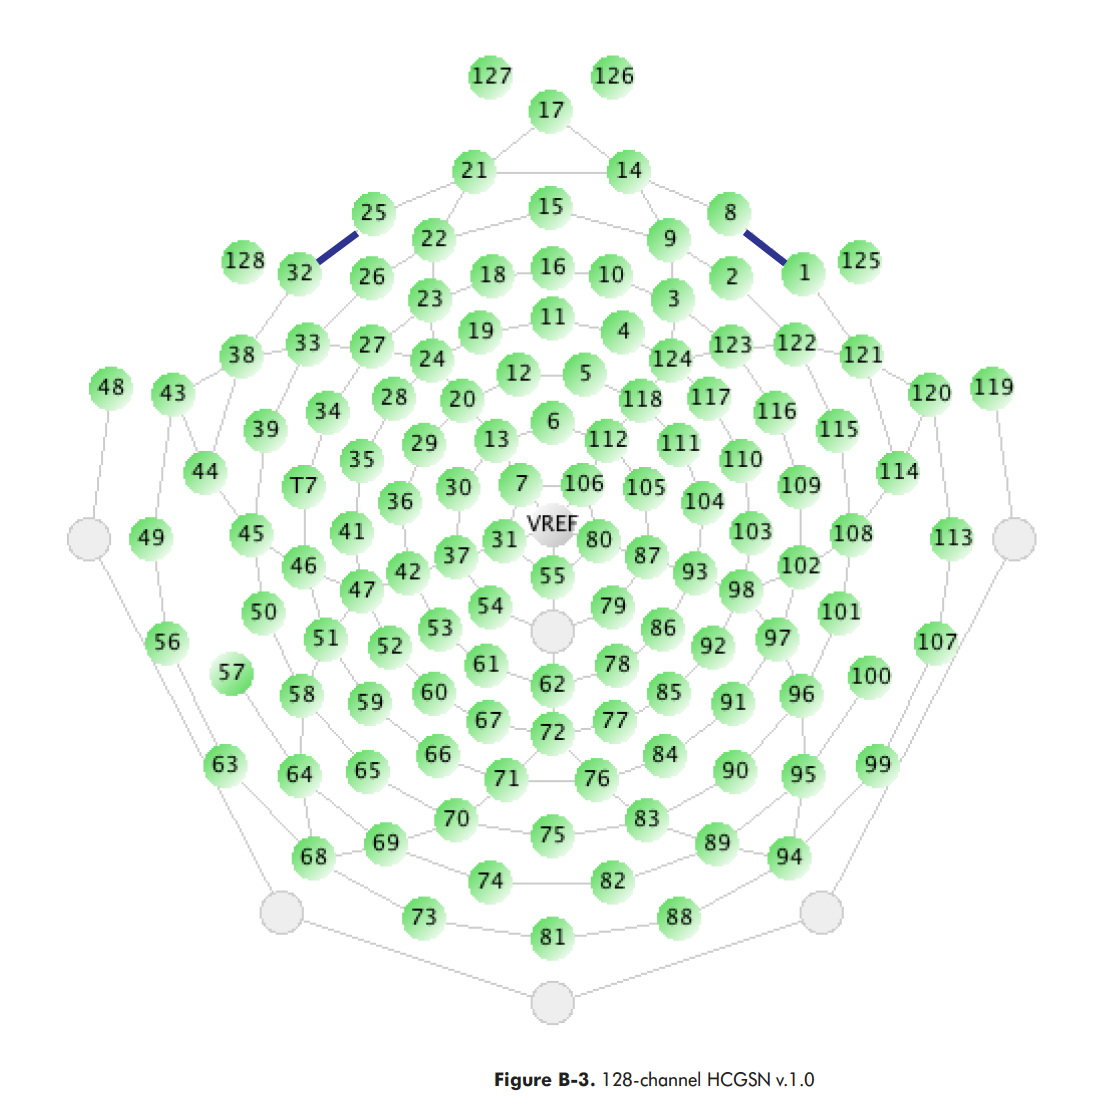sensor layout, to select seed electrodes (refelec) for inter-site phase locking



timeaxis = -3600:2:1500; 

PowerBsl = bslcorrWAMat_div(WaPower, [40:140]);
% select a baseline away from beginning and end of 
                                                 % the pre-stimulus period
                                                 % % try different ones and
                                                 % see what happens below
                                                 % in figure 3
                                                 
%length of baseline should be maximally sigT from beginning and also t0 - sigT 
%to avoid onset artefacts and anything that happens after stimulus onset
%you should have at least a cycle of your lowest frequency
%sigmaT=1/(2*pi*sigmaF)

PowerdB = 10*log10(PowerBsl); 


And now, a bunch of figures:

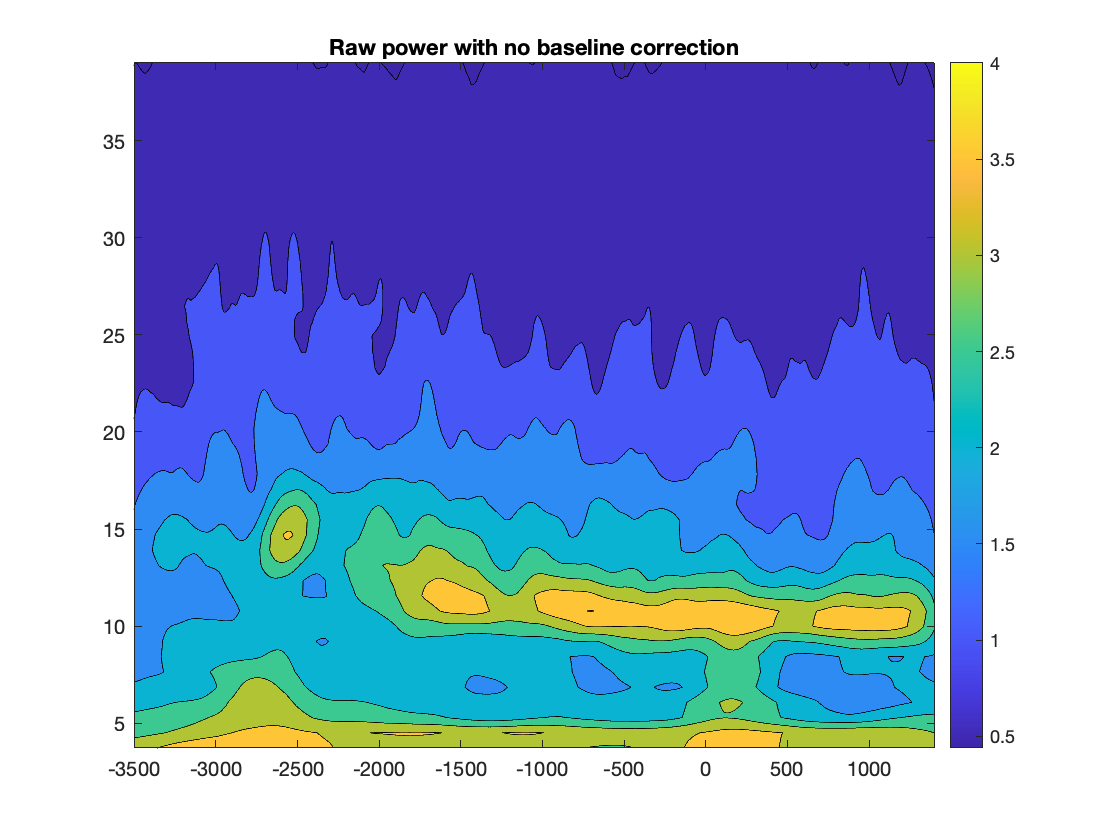

figure, contourf(timeaxis(50:2500), freqs_wanted, squeeze(WaPower(75, 50:2500, :))'), colorbar
title('Raw power with no baseline correction')

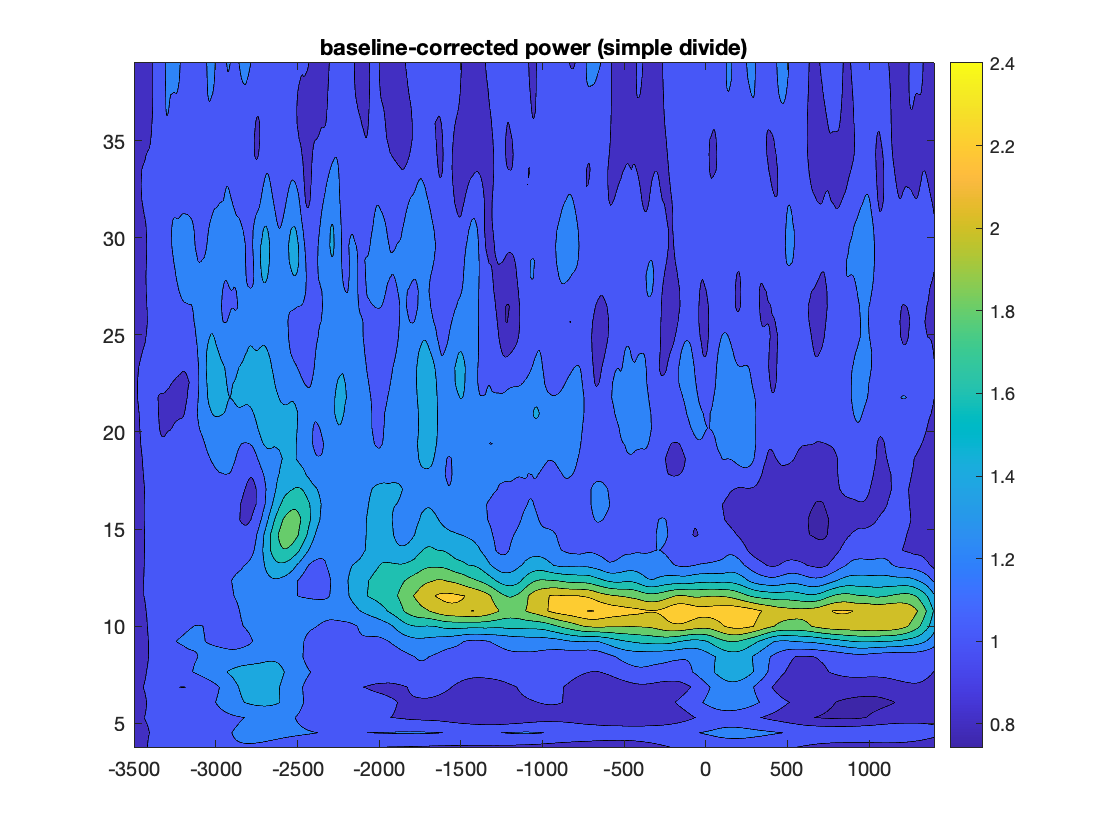


figure, contourf(timeaxis(50:2500), freqs_wanted, squeeze(PowerBsl(75, 50:2500, :))'), colorbar
title('baseline-corrected power (simple divide)')

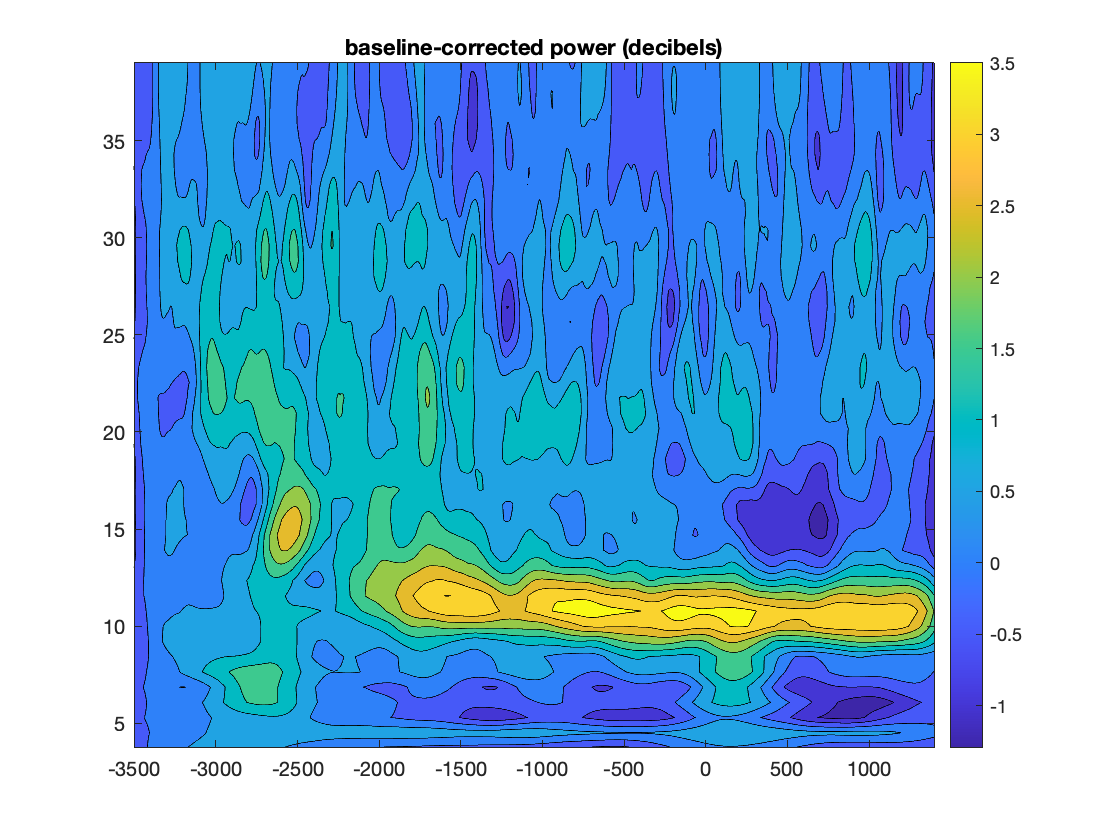


figure, contourf(timeaxis(50:2500), freqs_wanted, squeeze(PowerdB(75, 50:2500, :))'), colorbar
title('baseline-corrected power (decibels)')


% no baseline correction for Phase-locking - do you know why ? 


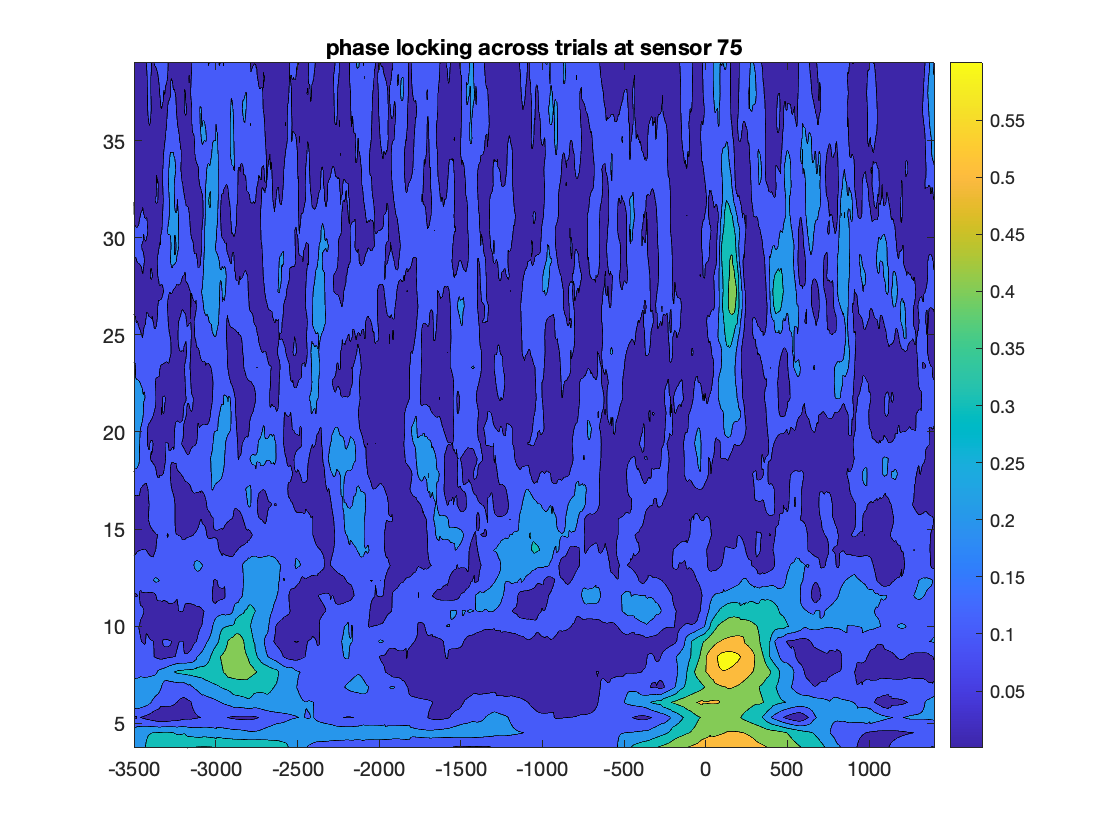

figure, contourf(timeaxis(50:2500), freqs_wanted, squeeze(PLI(75, 50:2500, :))'), colorbar
title('phase locking across trials at sensor 75')

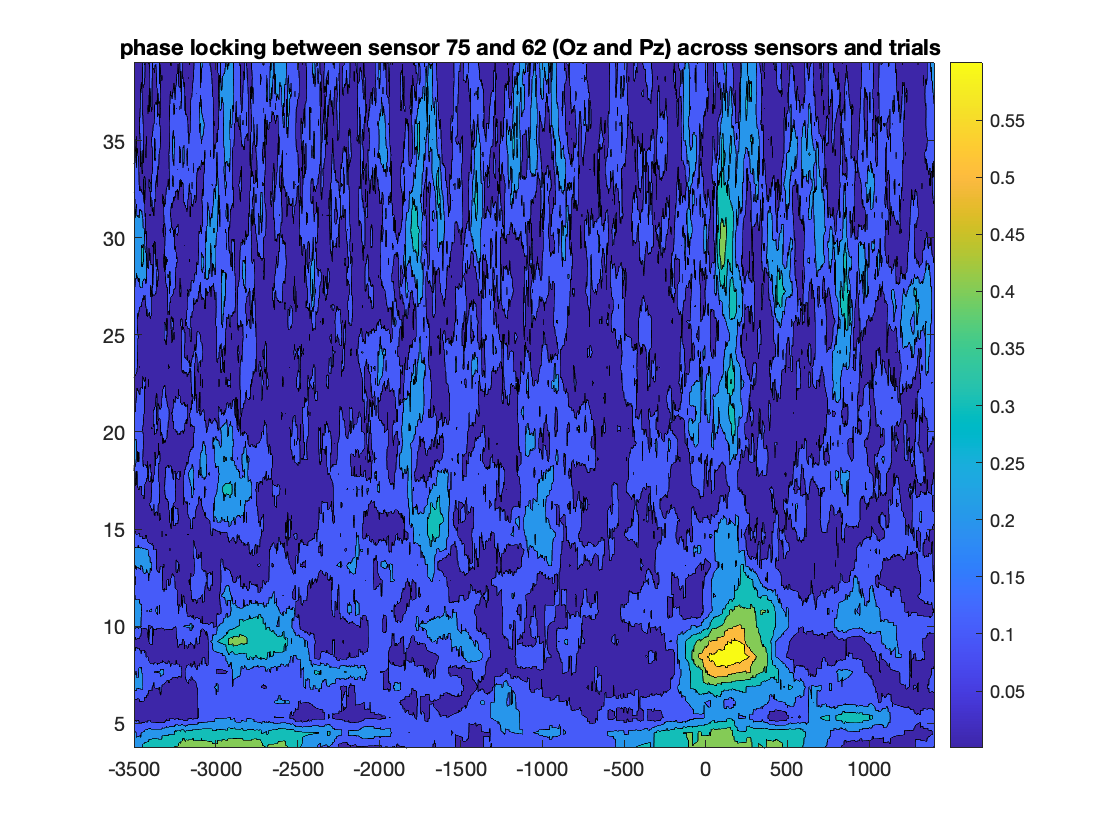

 
figure, contourf(timeaxis(50:2500), freqs_wanted, squeeze(PLIdiff(75, 50:2500, :))'), colorbar
title('phase locking between sensor 75 and 62 (Oz and Pz) across sensors and trials ')


%baseline corrected power (power change)


edit gener_wav  % change m and see what happens when you do it again...
% here you can change the m parameter; setting a lower m will give more
% resolution in higher frequencies. 

Measure the time and frequency resolution with an impulse response. This is an alternative to calculating the time and frequency resolution as discussed in the slides (day 2) 

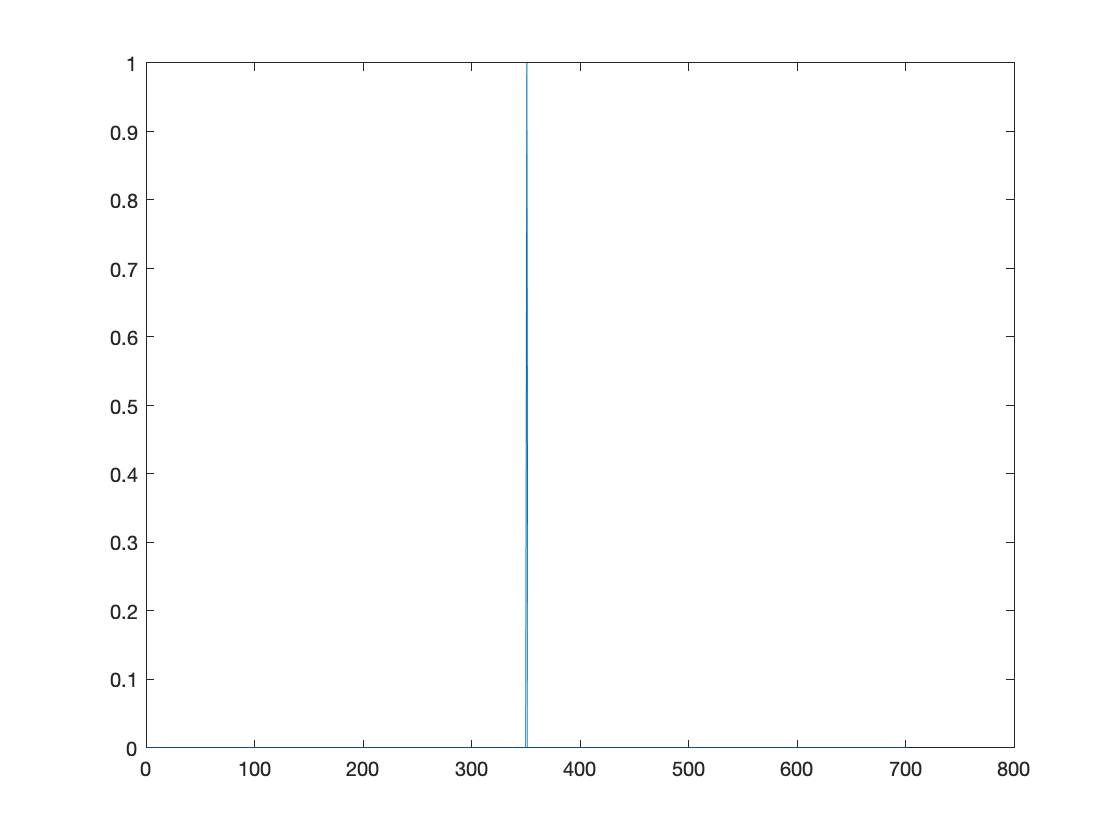


pulse = zeros(1,701);

pulse(351)=1;

figure, plot(pulse)


[WaPowerP] = wavelet_app_mat(pulse, 500, 13, 60, 1);

size of waveletMatrix
    48   701

 frequency step for delta_f0 = 1 is 
    0.7133

trial index of 
     1

.

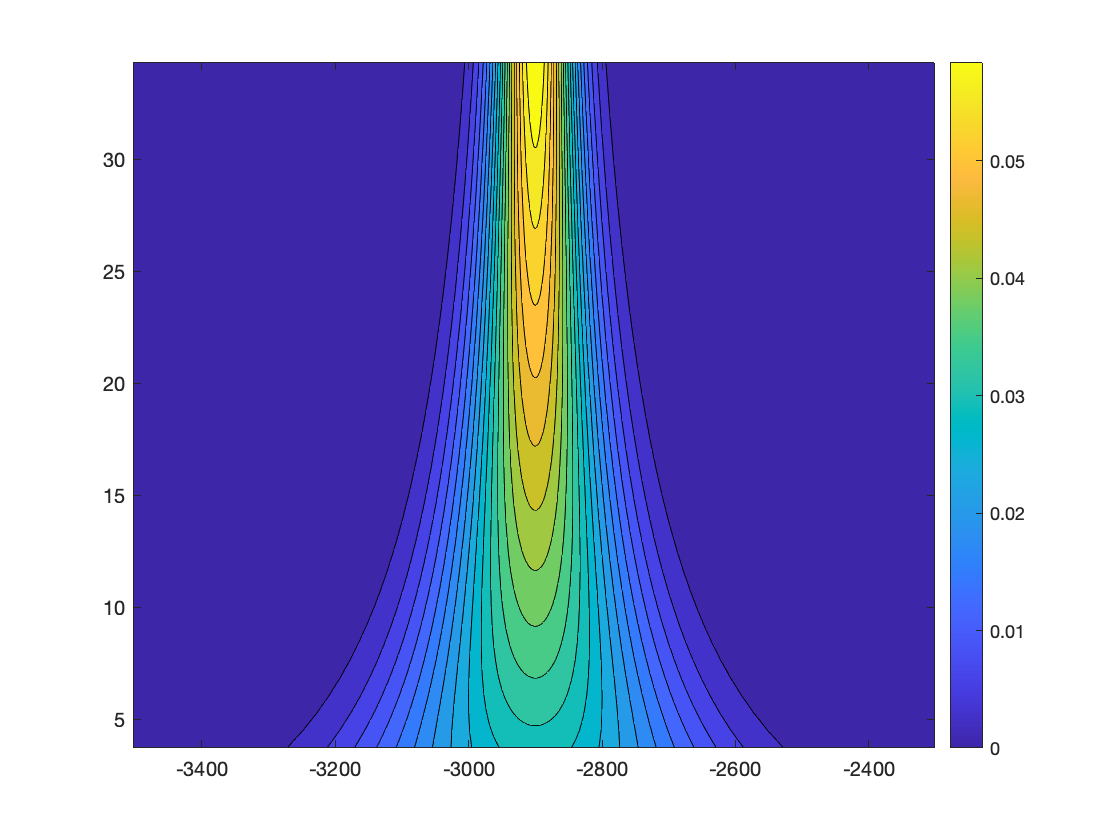


figure, contourf(timeaxis(50:650), freqs_wanted(1:40), squeeze(WaPowerP(1, 50:650, 1:40))', 20), colorbar